# Polymer Melt Flow Rate

## 0- Problem Statement

Polymer properties such as density, melt index, and melt flow rate must be kept within tight specifications for each grade. This case study is to analyze polymer production data to predict melt flow rate. See full [problem statement](http://apmonitor.com/pds/index.php/Main/PolymerMeltFlowRate).

**Background: **

There are gas phase and liquid slurry reactors that create polymers (polyethylene, polypropylene, polystyrene, and others) from chemical building blocks known as monomers (C2=, C3=, C4=, iC5=, and others). A catalyst is injected with the monomers under carefully controlled temperature and pressure conditions to cause a reaction that grows the polymer chains. Hydrogen is a chain transfer agent to stop the growth of the polymer chain. If the polymer chains grow too long then the polymer is too viscous for manufacturing in films, injection molding, or other applications.

If the polymer chains are too short then the polymer is soft and does not have the strength for the particular application such as a plastic bag, a car bumper, or washing machine drum. Regular lab samples from the reactor are used to keep the polymer at the right viscosity for each particular grade. The grade is specified by the customer and may include specifications for:

- Melt Index (Polyethylene)

- Melt Flow Rate (Polypropylene)

- Density

- Xylene Solubles (Measure of Polymer Crystallinity)

This case study focuses on measurements of [**Melt Flow Rate (MFR)**](https://en.wikipedia.org/wiki/Melt_flow_index) to determine the polymer viscosity based on reactor conditions. An accurate model is desirable so that the infrequent lab samples (every 2-8 hours) are supplemented with a virtual and continuous "soft sensor". A model that runs in real-time simulation alongside the physical reactor is called a digital twin.

**Objective: **

Develop a prediction of the reactor MFR from the [**polymer reactor data set**](http://apmonitor.com/pds/uploads/Main/polymer_reactor.txt). Report the correlation coefficient (R2) for predicting *ln(MFR)* in the test set. Randomly select values that split the data into a train (80%) and test (20%) set. Use [**Linear Regression**](http://apmonitor.com/pds/index.php/Main/LinearRegression), [**Neural Network (Deep Learning)**](http://apmonitor.com/pds/index.php/Main/MultilayerPerceptronNeuralNetwork), and another regression method of your choice. Discuss the performance of each. Submit source code and a summary memo (max 2 pages) of your results.

**Regression: **

Use 3 regression methods. Possible [**regression methods**](https://apmonitor.com/pds/notebooks/06_regression.html) are:

- [**Linear Regression**](http://apmonitor.com/pds/index.php/Main/LinearRegression)

- [**Neural Network (Deep Learning)**](http://apmonitor.com/pds/index.php/Main/MultilayerPerceptronNeuralNetwork)

- [**K-Nearest Neighbors**](http://apmonitor.com/pds/index.php/Main/KNearestNeighborsRegression)

- [**Support Vector Regressor**](http://apmonitor.com/pds/index.php/Main/SupportVectorRegressor)

**Data: **

The data file contains [**tags from process instruments**](https://apmonitor.com/pdc/index.php/Main/FeedbackControl). The specific meaning of the tags is unknown but the follow table is an educated guess based on the name and range of values:

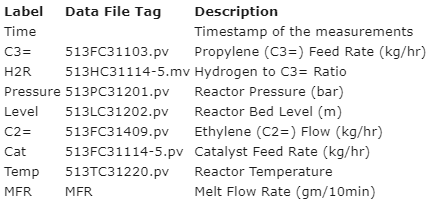

The data set has missing data and outliers so data visualization and exploration are needed to first cleanse the data set. Create a new data column as the natural log of MFR (*ln(MFR)*). The natural log of *MFR* is a better label (measured output) than *MFR*. This transform has a more linear relationship between the reactor conditions (inputs) and the predicted *ln(MFR)* output.

Use the [**TCLab Data Science modules 2-6**](https://github.com/APMonitor/data_science) ([**Import**](https://apmonitor.com/pds/notebooks/02_import_export.html), [**Analyze**](https://apmonitor.com/pds/notebooks/03_analyze.html), [**Visualize**](https://apmonitor.com/pds/notebooks/04_visualize.html), [**Prepare Data**](https://apmonitor.com/pds/notebooks/05_prepare_data.html), [**Regression**](https://apmonitor.com/pds/notebooks/06_regression.html)) as a template for analyzing and performing the regression.

**References**

- Roychadhury, A. [**Predict MFR of Polymer**](https://www.kaggle.com/apek1999/predict-mpv-of-polymer), Kaggle, Retrieved Jan 22, 2021.

- Hedengren, J.D. Allsford, K.V., and Ramlal, J., Moving Horizon Estimation and Control for an Industrial Gas Phase Polymerization Reactor, Proceedings of the American Control Conference (ACC), New York, NY, pp. 1353-1358, July 2007. [**Preprint**](https://apm.byu.edu/prism/uploads/Members/hedengren_acc2007.pdf)

## **1- Analyze**

**Import Polymer MFR Data**

url = 'http://apmonitor.com/pds/uploads/Main/polymer_reactor.txt';
data = readtable(url,'VariableNamingRule','preserve')

data = 2564×9 table
          Var1          513FC31103.pv    513HC31114-5.mv    513PC31201.pv    513LC31202.pv    513FC31409.pv    513FC31114-5.pv    513TC31220.pv    MFR
    ________________    _____________    _______________    _____________    _____________    _____________    _______________    _____________    ___

    0004-05-18 19:45        24857             0.153            30.415           79.658            50851            0.16399             80.4        3.4
    0004-05-18 21:45        25537             0.153            30.527           78.533            42230            0.12974           78.861        3.2
    0004-05-18 23:45        25689             0.153            30.356

Rename the columns `['Time','C3=','H2R','Pressure','Level','C2=','Cat','Temp','MFR']`

data = renamevars(data, data.Properties.VariableNames, ["Time","C3=","H2R","Pressure","Level","C2=","Cat","Temp","MFR"])

data = 2564×9 table
          Time           C3=      H2R     Pressure    Level      C2=       Cat       Temp     MFR
    ________________    _____    _____    ________    ______    _____    _______    ______    ___

    0004-05-18 19:45    24857    0.153     30.415     79.658    50851    0.16399      80.4    3.4
    0004-05-18 21:45    25537    0.153     30.527     78.533    42230    0.12974    78.861    3.2
    0004-05-18 23:45    25689    0.153     30.356     78.843    45336       0.15    78.818    3.2
    0004-06-18 01:45    25099    0.153     30.894     79.174    43077    0.15154    79.023    3.1
    0004-06-18 03:45    24854     0.15     30.681     78.677    40404    0.12258    7

Create a new column for the natural log of (MFR) as `lnMFR`

data.lnMFR = log(data.MFR)

data = 2564×10 table
          Time           C3=      H2R     Pressure    Level      C2=       Cat       Temp     MFR    lnMFR 
    ________________    _____    _____    ________    ______    _____    _______    ______    ___    ______

    0004-05-18 19:45    24857    0.153     30.415     79.658    50851    0.16399      80.4    3.4    1.2238
    0004-05-18 21:45    25537    0.153     30.527     78.533    42230    0.12974    78.861    3.2    1.1632
    0004-05-18 23:45    25689    0.153     30.356     78.843    45336       0.15    78.818    3.2    1.1632
    0004-06-18 01:45    25099    0.153     30.894     79.174    43077    0.15154    79.023    3.1 

Use the `.describe()` function to get a summary of the data.

% Remove Nan's
data = data(~any(ismissing(data(:,2:end)),2),2:end); % we were cutting too many point off original code
%data = data(~any(ismissing(data),2),2:end);

% Print Statistics Values
fprintf('C3=')

C3=

statistics(data.("C3="))

ans = struct with fields:
    count: 2484
     mean: 2.5305e+04
      std: 1.7062e+03
      min: 1.6106e+04
      max: 3.0084e+04
       Q1: 2.4361e+04
       Q2: 2.5364e+04
       Q3: 2.6398e+04


fprintf('H2R')

H2R

statistics(data.("H2R"))

ans = struct with fields:
    count: 2484
     mean: 0.1837
      std: 0.0722
      min: 0
      max: 0.9800
       Q1: 0.1400
       Q2: 0.1750
       Q3: 0.2020


fprintf('Pressure')

Pressure

statistics(data.("Pressure"))

ans = struct with fields:
    count: 2484
     mean: 30.6637
      std: 0.4233
      min: 26.9463
      max: 32.6743
       Q1: 30.4460
       Q2: 30.6226
       Q3: 30.9260


fprintf('Level')

Level

statistics(data.("Level"))

ans = struct with fields:
    count: 2484
     mean: 77.6511
      std: 0.9196
      min: 74.5760
      max: 83.8417
       Q1: 76.9909
       Q2: 77.4945
       Q3: 78.2110


fprintf('C2=')

C2=

statistics(data.("C2="))

ans = struct with fields:
    count: 2484
     mean: 4.2525e+04
      std: 1.1332e+04
      min: 9.6105e+03
      max: 1.0607e+05
       Q1: 3.4795e+04
       Q2: 4.1551e+04
       Q3: 5.0011e+04


fprintf('Cat')

Cat

statistics(data.("Cat"))

ans = struct with fields:
    count: 2484
     mean: 0.1385
      std: 0.0419
      min: 0.0222
      max: 0.6780
       Q1: 0.1138
       Q2: 0.1330
       Q3: 0.1571


fprintf('Temp')

Temp

statistics(data.("Temp"))

ans = struct with fields:
    count: 2484
     mean: 80.1444
      std: 0.8236
      min: 77.7601
      max: 91.5665
       Q1: 79.6774
       Q2: 80.0443
       Q3: 80.4966


fprintf('MFR')

MFR

statistics(data.("MFR"))

ans = struct with fields:
    count: 2484
     mean: 8.0366
      std: 5.0765
      min: 1.5000
      max: 38
       Q1: 3.7000
       Q2: 4.3000
       Q3: 12.8000


fprintf('lmMFR')

lmMFR

statistics(data.('lnMFR'))

ans = struct with fields:
    count: 2484
     mean: 1.8818
      std: 0.6360
      min: 0.4055
      max: 3.6376
       Q1: 1.3083
       Q2: 1.4586
       Q3: 2.5494


## **2- Visualize**

**Pair Plot**

A pair plot shows the correlation between variables.

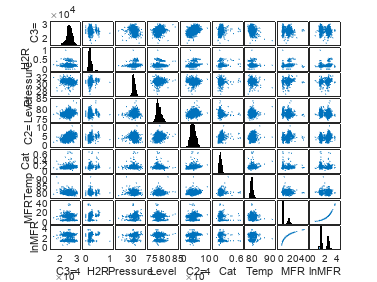

%%Plot everything except time column 
figure;
[~,AX] = plotmatrix(table2array(data(:,1:end)));

% Label y axis
ylabel(AX(1,1),'C3=')
ylabel(AX(2,1),'H2R')
ylabel(AX(3,1),'Pressure')
ylabel(AX(4,1),'Level')
ylabel(AX(5,1),'C2=')
ylabel(AX(6,1),'Cat')
ylabel(AX(7,1),'Temp')
ylabel(AX(8,1),'MFR')
ylabel(AX(9,1),'lnMFR')

% Label x axis
xlabel(AX(9,1),'C3=')
xlabel(AX(9,2),'H2R')
xlabel(AX(9,3),'Pressure')
xlabel(AX(9,4),'Level')
xlabel(AX(9,5),'C2=')
xlabel(AX(9,6),'Cat')
xlabel(AX(9,7),'Temp')
xlabel(AX(9,8),'MFR')
xlabel(AX(9,9),'lnMFR')

**Joint Plot**

A joint plot shows two variables, with the univariate and joint distributions. 

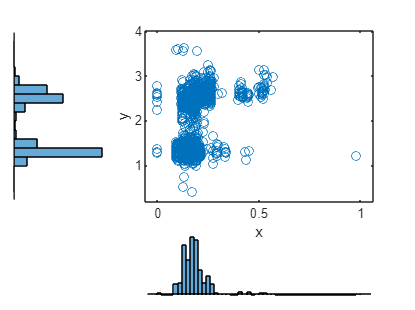

figure;
scatterhist(data.H2R,data.lnMFR)

**Histogram**

Try a histogram to show the number of binned samples of `lnMFR`

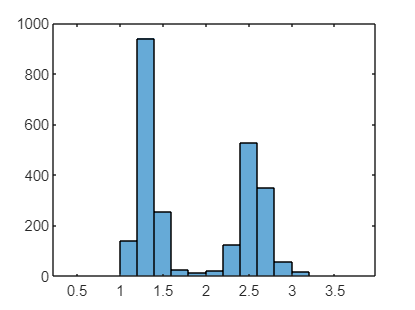

figure;
histogram(data.lnMFR)

**Heat Map**

Create a correlation heat map

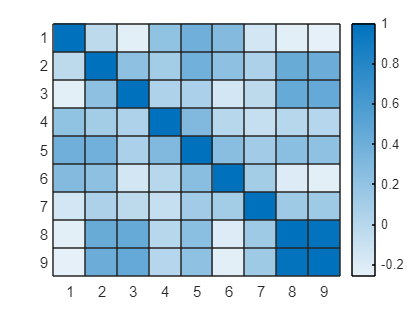

% create the correlation of the data
correlation = corrcoef(table2array(data(:,1:end)));

% Plot the heat map
figure;
heatmap(correlation)

## 3-Prepare Data

**Clean Data**

You can clean data via the Live Scripts. View the following link to view how: [Find, fill, or remove outliers in the Live Editor - MATLAB (mathworks.com)](https://www.mathworks.com/help/matlab/ref/cleanoutlierdata.html)

There are several graphical techniques to help detect outliers. A box or histogram plot shows outlying points.

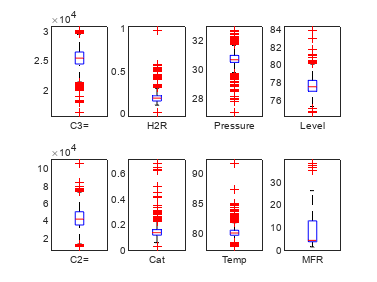

figure;
for i = 1:8
    subplot(2,4,i);
    c = data.Properties.VariableNames(i);
    boxplot(data.(c{1}),'Labels',c{1});
end
hold off

Remove outliers by removing select rows such as with:

data = data(data.H2R < 0.7,:);
data = data(data.H2R > 0.01,:);

to keep only values of `H2R` (Hydrogen to Monomer ratio) that are between 0.01 and 0.7.

Show the boxplot again to verify that the data set does not have outliers.

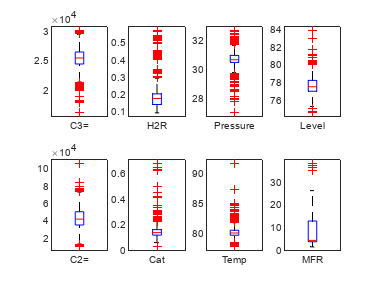

figure;
for i = 1:8
    subplot(2,4,i);
    c = data.Properties.VariableNames(i);
    boxplot(data.(c{1}),'Labels',c{1});
end
hold off

Remove MFR and keep only ln(MFR) as `lnMFR`. You can delete a column using removevars(data,"x").

data = removevars(data,("MFR"));

**Scale Data**

Scale data with the normalize, rescale or zscore.

% Scale Data
Z = zscore(table2array(data(:,1:end)));

% Convert back to a table and rename columns
data1 = array2table(Z);
data1.Properties.VariableNames = data.Properties.VariableNames(:,1:end);

**Divide Data**

Data is divided into train and test sets to separate a fraction of the rows for evaluating classification or regression models. A typical split is 80% for training and 20% for testing, although the range depends on how much data is available and the objective of the study.

% Set your ratio for train, val, and test
trainRatio = .8;
valRatio = 0;
testRatio = .2;

% Split data
[trainInd,valInd,testInd] = dividerand(length(data1.Level),trainRatio,valRatio,testRatio);
x_train = data1(trainInd, :);
x_test = data1(testInd, :);

## 4-MFR Regression

The is objective is to minimize a loss function such as a sum of squared errors between the measured and predicted values:


$$\textrm{Loss}=\sum_{i=1}^n {\left(y_i -z_i \right)}^2$$


where `n` is the number of observations. Regression requires labelled data (output values) for training. Classification, on the other hand, can either be supervised (with `z` measurements, labels) or unsupervised (no labels, `z` measurements).

**Linear Regression**

There are many model forms such as linear, polynomial, and nonlinear. A familiar linear model is a line with slope `a` and intercept `b` with `y = a x + b`.

p1 = polyfit(data1.("H2R"),data1.("lnMFR"),1);

Determine the slope and intercept that minimize the sum of squared errors (least squares) between the predicted `lnMFR` and measured `lnMFR` output using `H2R` as the input.

intercept = p1(1)

intercept = 0.4400

slope = p1(2)

slope = -5.6815e-15

Perform standard Ordinary Least Squares (OLS) analysis with a nice report summary.

% fit the data to a model
mdl = fitlm(data1);

% Display the summary
display(mdl);

mdl = Linear regression model:
    lnMFR ~ 1 + C3= + H2R + Pressure + Level + C2= + Cat + Temp

Estimated Coefficients:
                    Estimate         SE          tStat         pValue  
                   ___________    ________    ___________    __________

    (Intercept)    -6.5524e-15    0.014988    -4.3717e-13             1
    C3=               -0.13948    0.018387        -7.5855    4.6637e-14
    H2R                0.36825    0.017497         21.046    1.4497e-90
    Pressure           0.27429    0.016261         16.868    1.6888e-60
    Level            -0.065036    0.015927        -4.0834    4.5793e-05
    C2=                0.19008    0.019046         9.9801    5.0614e-23
    Cat               -0.30092    0.016571      

Select Best Features

Rank the features to determine the best set that predicts `lnMFR`.

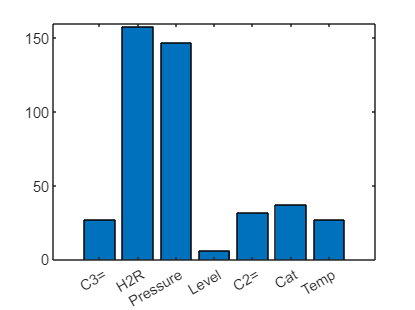

% fit the data to a model
[fit, scores] = fscchi2(data1,"lnMFR");

% Plot results
figure;
bar(scores)
features = data.Properties.VariableNames(1:end-1);
set(gca, 'XTick', 1:length(features), 'XTickLabel', features)

### **Machine Learning**

Machine learning is computer algorithms and statistical models that rely on patterns and inference. They perform a specific task without explicit instructions. Machine learned regression models can be as simple as linear regression or as complex as deep learning. 

**Regression Learner App**

1. Click APPS in the ribbon and select Regression Learner.

2. Click New Session in the pop-up

3. Select x_train in the Data Set Variable and ensure the Response variable is lnMFR.

3a. Unbox everything other than H2R and Pressure under the Predictors section. It should look like the following.

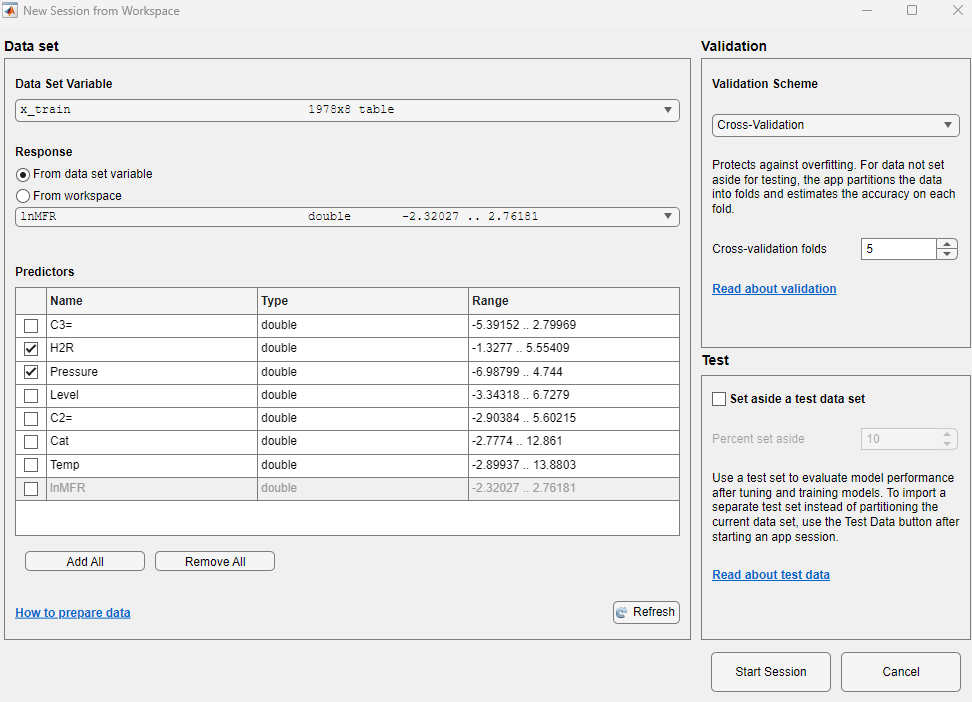

4. Click Start Session in the bottom right.

5. By default, the Fine Tree model will be selected. Under Models in the ribbon, select the models that you would like.

6. Once complete, you can view the accuracy by clicking the model on the left and then click summary.

7. Import test data on the right hand side and select x_test and select import.

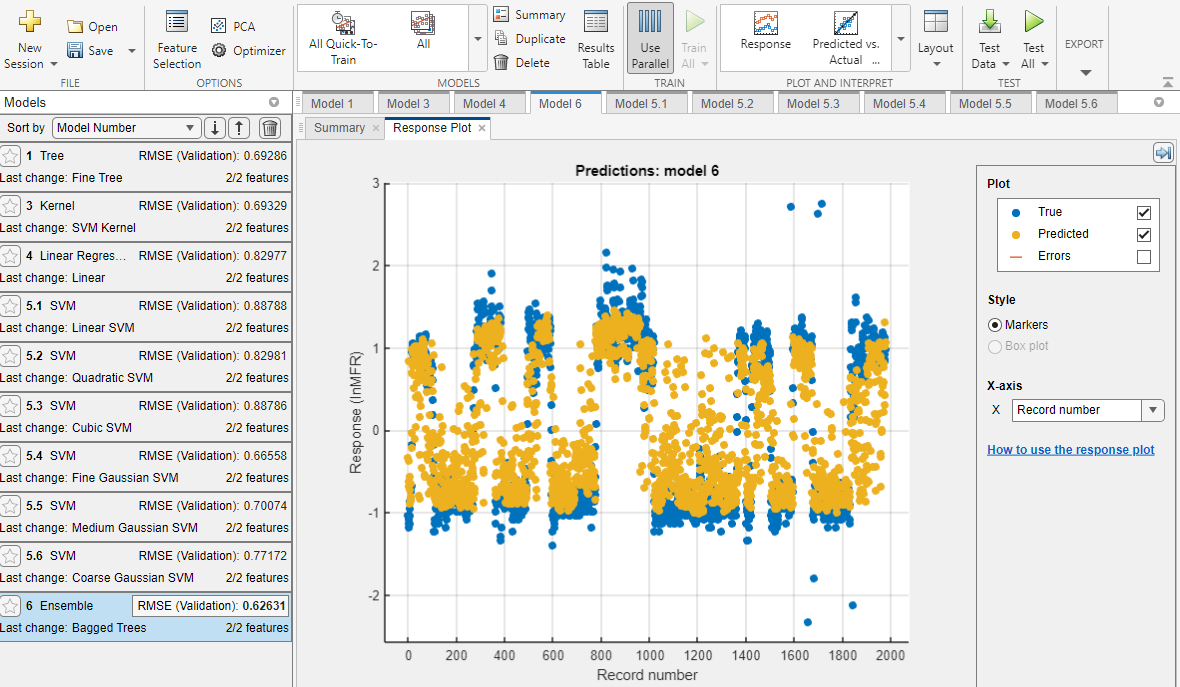

8. Click Test all.

9. You can now view all results.

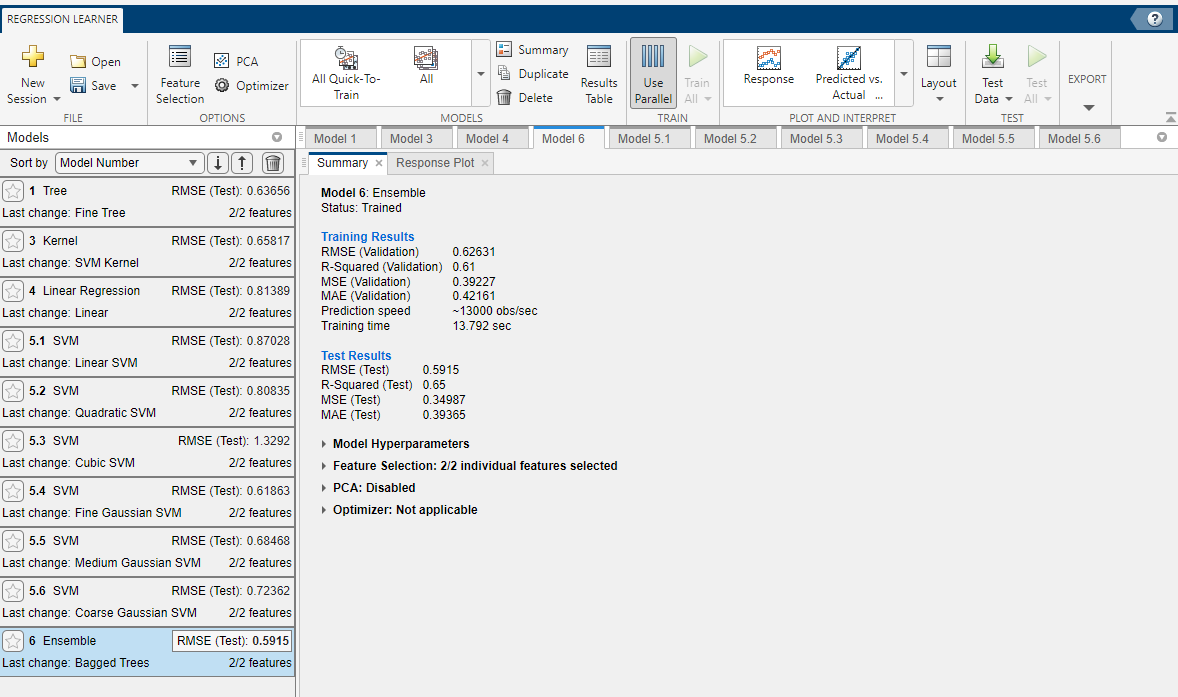

**Linear Regression**

The simplest regressor is a linear model.

This model is not expected to perform very well with the nonlinear data but it does predict the slope of the data.

fprintf('Linear Regression')

Linear Regression


% Create points for plotting surface
xp = (-5:0.2:5);     
yp = (-5:0.2:5); 
[XP, YP] = meshgrid(xp, yp); 

% convert values to array
x = table2array(x_train(:,{'H2R','Pressure'})); 
y = x_train.lnMFR; 

% fit model
method = fitlm(x,y); 

% predict using model
zp = predict(method,[XP(:) YP(:)]); 
ZP = reshape(zp,size(XP)); 

% calculate the Rsquared value
r2 = method.Rsquared.Ordinary; 
fprintf('R^2: %0.4f\n', r2); 

R^2: 0.3128


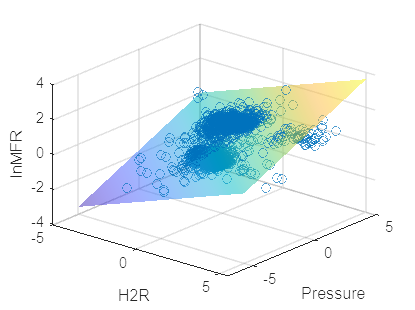


% Plot 3D figure
figure; 
ax = axes('XGrid', 'on', 'XMinorGrid', 'on', 'YGrid', 'on', 'YMinorGrid', 'on'); 
scatter3(x_train.H2R, x_train.Pressure, x_train.lnMFR); 
alpha(0.7);
hold on; 
surf(XP,YP,ZP,'EdgeColor','none','FaceColor','interp','FaceAlpha',0.5); 
hold off; 
colormap(ax, 'parula'); 
xlabel('H2R'); 
ylabel('Pressure'); 
zlabel('lnMFR'); 
view(40,30); 
grid on; 

**K-Nearest Neighbors**

David Ferreira (2023). k-Nearest Neighbors (kNN) Regressor (https://github.com/ferreirad08/kNNeighborsRegressor/releases/tag/1.0.1), GitHub. Retrieved March 2, 2023.

fprintf('K-Nearest Neighbors')

K-Nearest Neighbors


% Prepare Knnmodel 
knnmodel = kNNeighborsRegressor(20);
knnmodel = knnmodel.fit(x,y);
ycal = predict(knnmodel,x);
kzp = knnmodel.predict([XP(:) YP(:)]);
KnnZp = reshape(kzp,size(XP));

% calculate the Rsquared value
r2 = 1 - sum((y - ycal').^2)/sum((y - mean(y)).^2);
fprintf('R^2: %0.4f\n', r2); 

R^2: 0.6174


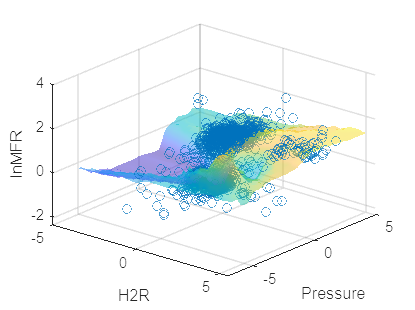


% Plot 3D figure
figure; 
ax = axes('XGrid', 'on', 'XMinorGrid', 'on', 'YGrid', 'on', 'YMinorGrid', 'on'); 
scatter3(x_train.H2R, x_train.Pressure, x_train.lnMFR); 
alpha(0.7);
hold on; 
surf(XP,YP, KnnZp,'EdgeColor','none','FaceColor','interp','FaceAlpha',0.5); 
hold off; 
colormap(ax, 'parula'); 
xlabel('H2R'); 
ylabel('Pressure'); 
zlabel('lnMFR'); 
view(40,30); 
grid on; 

**Support Vector Regressor**

Use a Support Vector Regressor (SVR) to perform the regression.

What are the hyper-parameters for this regressor?

fprintf('Support Vector Regresso')

Support Vector Regresso


% Create Rvsm model
rvsmmod = fitrsvm(x,y);
ycal = predict(rvsmmod,x);
rvsp = predict(rvsmmod,[XP(:) YP(:)]);
RVSMZp = reshape(rvsp,size(XP));

% calculate the Rsquared value
r2 = 1 - sum((y - ycal).^2)/sum((y - mean(y)).^2);
fprintf('R^2: %0.4f\n', r2); 

R^2: 0.2052


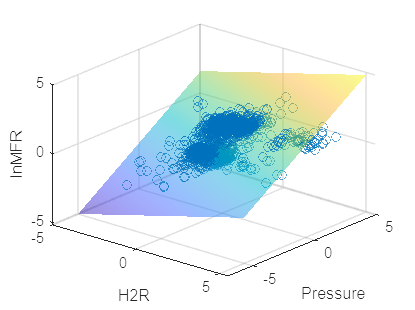


% Plot 3D figure
figure; 
ax = axes('XGrid', 'on', 'XMinorGrid', 'on', 'YGrid', 'on', 'YMinorGrid', 'on'); 
scatter3(x_train.H2R, x_train.Pressure, x_train.lnMFR); 
alpha(0.7);
hold on; 
surf(XP,YP, RVSMZp,'EdgeColor','none','FaceColor','interp','FaceAlpha',0.5); 
hold off; 
colormap(ax, 'parula'); 
xlabel('H2R'); 
ylabel('Pressure'); 
zlabel('lnMFR'); 
view(40,30); 
grid on; 

**Multlayer Perceptron (Neural Network)**

Train a neural network to predict the lnMFR

fprintf('Neural Network')

Neural Network


% Fit classification Neural Network
neunet = fitrnet(x,y);
ycal = predict(neunet,x);
nnp = predict(neunet,[XP(:) YP(:)]);
NNp = reshape(nnp,size(XP));

% calculate the Rsquared value
r2 = 1 - sum((y - ycal).^2)/sum((y - mean(y)).^2);
fprintf('R^2: %0.4f\n', r2);

R^2: 0.5742


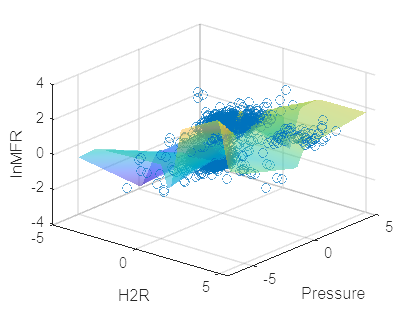


% Plot 3D figure
figure; 
ax = axes('XGrid', 'on', 'XMinorGrid', 'on', 'YGrid', 'on', 'YMinorGrid', 'on'); 
scatter3(x_train.H2R, x_train.Pressure, x_train.lnMFR); 
alpha(0.7);
hold on; 
surf(XP,YP, NNp,'EdgeColor','none','FaceColor','interp','FaceAlpha',0.5); 
hold off; 
colormap(ax, 'parula'); 
xlabel('H2R'); 
ylabel('Pressure'); 
zlabel('lnMFR'); 
view(40,30); 
grid on; 

### Additional Features

Repeat the analysis but now generate a parity plot of measured versus predicted values with all features, not just Pressure and H2R.

**Linear Regression**

fprintf('Linear Regression')

Linear Regression


%Create new X which contains all variables  
X_new =  table2array(x_train(:,1:end-1));

% fit model
new_method = fitlm(X_new,y); 

%predict 
LRNewMod = predict(new_method, X_new);

% calculate the Rsquared value
r2 = new_method.Rsquared.Ordinary; 
fprintf('R^2: %0.4f\n', r2);

R^2: 0.4474


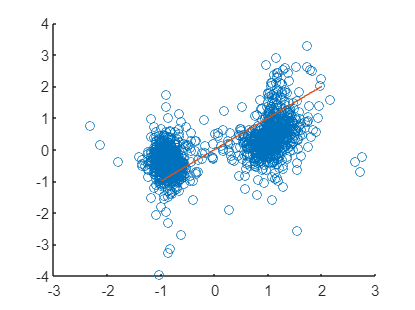


%%Plot 
figure;
scatter(y,LRNewMod)
hold on;
plot([-1,2],[-1,2])
hold off;

**K-Nearest Neighbors**

fprintf('K-Nearest Neighbors')

K-Nearest Neighbors


%Create Knn model
knnmodel = fitcknn(X_new,y,NumNeighbors=20);
kzp = predict(knnmodel,X_new);

% calculate the Rsquared value
r2 = 1 - sum((y - kzp).^2)/sum((y - mean(y)).^2);
fprintf('R^2: %0.4f\n', r2);

R^2: 0.4515


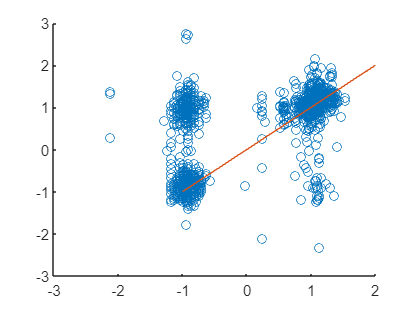


%%Plot 
figure;
scatter(kzp,y)
hold on;
plot([-1,2],[-1,2])
hold off;

**Support Vector Regressor**

fprintf('Support Vector Regressor')

Support Vector Regressor


% Create SVR model
rvsmmod_new = fitrsvm(X_new,y);
rvsp_new = predict(rvsmmod_new,X_new);

% calculate the Rsquared value
r2 = 1 - sum((y - rvsp_new).^2)/sum((y - mean(y)).^2);
fprintf('R^2: %0.4f\n', r2);

R^2: 0.3898


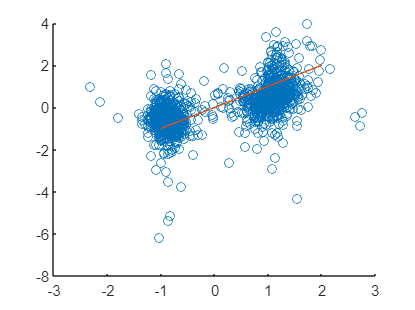


%%Plot 
figure;
scatter(y, rvsp_new)
hold on;
plot([-1,2],[-1,2])
hold off;

**Neural Network**

fprintf('Neural Network')

Neural Network


% Create Neural Network Model
neunet_new = fitrnet(X_new,y);
nnp_new = predict(neunet_new,X_new);

% calculate the Rsquared value
r2 = 1 - sum((y - nnp_new).^2)/sum((y - mean(y)).^2);
fprintf('R^2: %0.4f\n', r2);

R^2: 0.7375


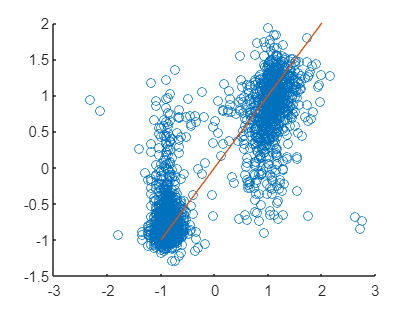


%%Plot 
figure;
scatter(y, nnp_new)
hold on;
plot([-1,2],[-1,2])
hold off;

**Supplementary Functions**

function statistics = statistics(data)
    statistics.count = numel(data); % count
    statistics.mean = mean(data); % mean
    statistics.std = std(data); % standard deviation
    statistics.min = min(data); % min
    statistics.max = max(data); % max
    statistics.Q1 = prctile(data,25); % 1st quartile (25th percentile)
    statistics.Q2 = prctile(data,50); % 2nd quartile (50th percentile) = median
    statistics.Q3 = prctile(data,75); % 3rd quartile (75th percentile)
end
